## **1.a.**

caso 1: o aluno estudou a matéria da pergunta. neste caso o aluno tem 100% de probabilidade de acertar a pergunta e a probabilidade de este caso acontecer é 0.60.

caso 2: o aluno não estudou a matéria da pergunta. neste caso ele escolhe dentre as 4 respostas disponíveis uma ao acaso, ou seja, 1/4 = 0.25. a probabilidade disto acontecer é 1 - 0.60 = 0.40.

p(acertar) = p(estudou) . p(acertar | estudou) + p(não estudou) . p(acertar | não estudou) = (0.60 * 1) + (0.40 * 0.25) = 0.60 + 0.10 = 0.70.

ps: o professor disse para me despachar então vou ser direto ao assunto. se não perceberes alguma cena, luta para entender. 

p = 0.6;
n = 4;

resla = p + (1 -p)/n

resla = 0.7000

## **1.b.**

p(e) = probabilidade de ter estudado = 0.70

p(a) = probabilidade de acertar = ?

p(e|a) = ( p(a|e)*p(e) ) / p(a)

p(a|e) = probabilidade de acertar sendo que estudou = 1

p(a) = p(e) * p(a|e) + p(~e) * p(a|~e)

p(a|~e) = 1/5 = 0.20

p(a) = 0.70 * 1 + 0.30 * 0.20 = 0.76

p(e|a) = ( 1*0.70 ) / 0.76 = 0.921

p = 0.7;
n = 5;

reslb = p*n/(1 + (n-1)*p)

reslb = 0.9211

## **1.c.**

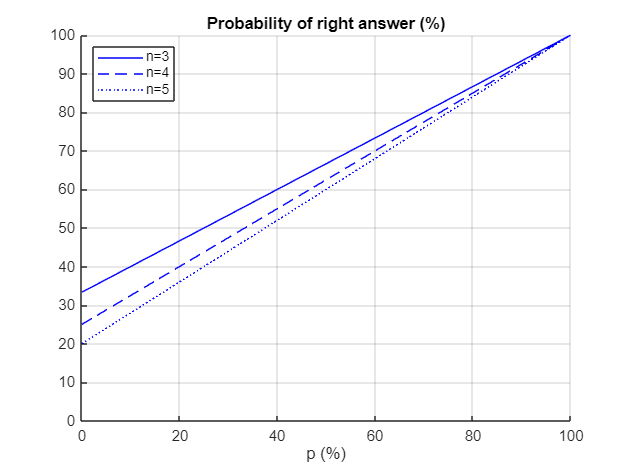

p = linspace(0, 1, 100);

figure;
hold on;

n = 3;
prob = p + (1-p)/n;
plot(p*100, prob*100, 'b-');

n = 4;
prob = p + (1-p)/n;
plot(p*100, prob*100, 'b--');

n = 5;
prob = p + (1-p)/n;
plot(p*100, prob*100, 'b:');

xlabel('p (%)');
title('Probability of right answer (%)');
legend('n=3','n=4','n=5', 'location', 'northwest');
grid on;
axis([0 100 0 100]);
hold off;

## **1.d.**

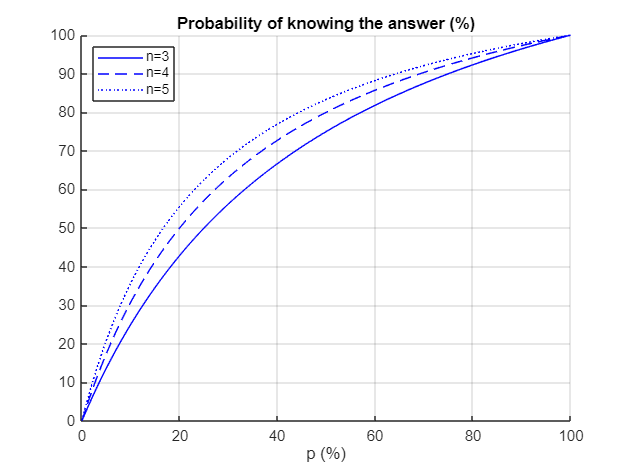

p = linspace(0, 1, 100);

figure;
hold on;

n = 3;
prob = p*n./(1 + (n-1)*p);
plot(p*100, prob*100, 'b-');

n = 4;
prob = p*n./(1 + (n-1)*p);
plot(p*100, prob*100, 'b--');

n = 5;
prob = p*n./(1 + (n-1)*p);
plot(p*100, prob*100, 'b:');

xlabel('p (%)');
title('Probability of knowing the answer (%)');
legend('n=3','n=4','n=5', 'location', 'northwest');
grid on;
axis([0 100 0 100]);
hold off;